Root of Equations

by: 13621060 フィズ Hafizh Renanto Akhmad

Note: You may run this on separate .m files, by copying one section (either Bisection or False Position) followed by the functions.

fsym = @f;

format long

xr = fzero(fsym,[0 2]);

fprintf("xt = %.15f", xr);

xt = 1.467390399281356

1.    Bisection Method

First ver.

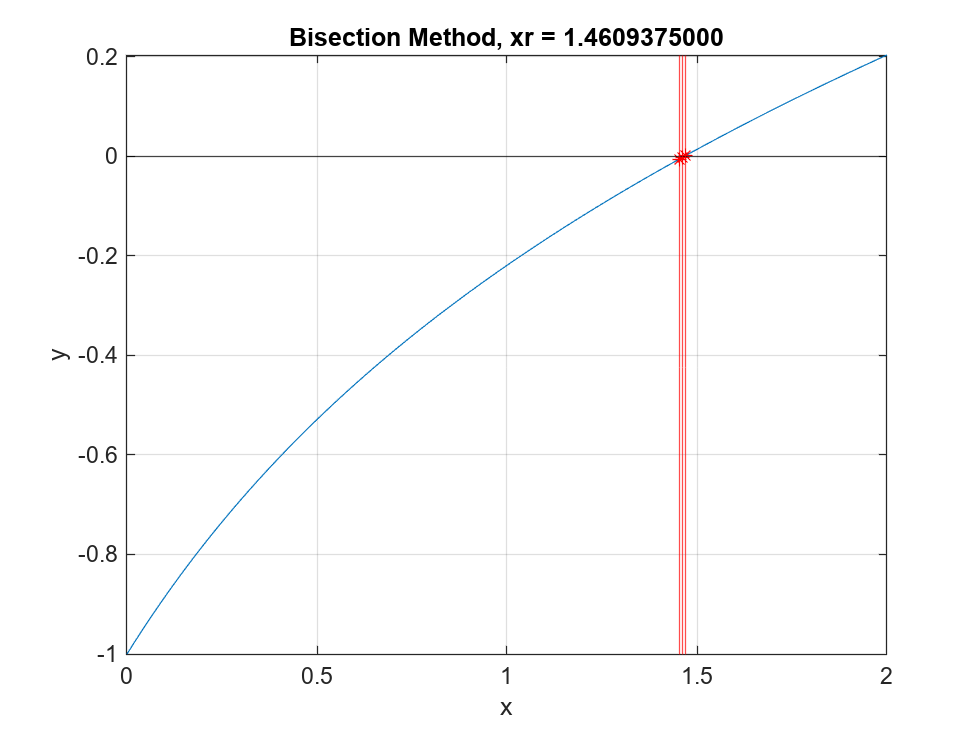

xlower = 0.000000000000000


xupper = 2.000000000000000


xmid = 1.000000000000000


f(xlower) = -1.000000000000000


f(xupper) = 0.203144995579288


f(xmid) = -0.219281375825817


Approximate error = 100.000000000000000

True error = 31.851809818999570

Iteration of 1


xlower = 1.000000000000000


xupper = 2.000000000000000


xmid = 1.500000000000000


f(xlower) = -0.219281375825817


f(xupper) = 0.203144995579288


f(xmid) = 0.013631635292986


Approximate error = 33.333333333333329

True error = 2.222285271500643

Iteration of 2


xlower = 1.000000000000000


xupper = 1.500000000000000


xmid = 1.250000000000000


f(xlower) = -0.219281375825817


f(xupper) = 0.013631635292986


f(xmid) = -0.095923372126535


Approximate error = 20.000000000000000

True error = 14.814762273749466

Iteration of 3


xlower = 1.250000000000000


xupper = 1.500000000000000


xmid = 1.375000000000000


f(xlower) = -0.095923372126535


f(xupper) = 0.013631635292986


f(xmid) = -0.039647750455329


Approximate error = 9.090909090909092

True error = 6.296238501124411

Iteration of 4


xlower = 1.375000000000000


xupper = 1.500000000000000


xmid = 1.437500000000000


f(xlower) = -0.039647750455329


f(xupper) = 0.013631635292986


f(xmid) = -0.012657431431668


Approximate error = 4.347826086956522

True error = 2.036976614811884

Iteration of 5


xlower = 1.437500000000000


xupper = 1.500000000000000


xmid = 1.468750000000000


f(xlower) = -0.012657431431668


f(xupper) = 0.013631635292986


f(xmid) = 0.000572004304339


Approximate error = 2.127659574468085

True error = 0.092654328344380

Iteration of 6


xlower = 1.437500000000000


xupper = 1.468750000000000


xmid = 1.453125000000000


f(xlower) = -0.012657431431668


f(xupper) = 0.000572004304339


f(xmid) = -0.006021153364387


Approximate error = 1.075268817204301

True error = 0.972161143233752

Iteration of 7


xlower = 1.453125000000000


xupper = 1.468750000000000


xmid = 1.460937500000000


f(xlower) = -0.006021153364387


f(xupper) = 0.000572004304339


f(xmid) = -0.002719226891154


Approximate error = 0.534759358288770

True error = 0.439753407444686

Iteration of 8


clc, clf

% Bisection Method

% Initializing first two points
xlower = 0; 
xupper = 2;

% Initialize number of iteration
iter = 0;

% Intialize number of approximate error (Chapra page 132)
ea = abs(xupper - xlower) / (xupper + xlower) * 100;

% Declare stopping error
es = 1;

% Declare boolean
stop_iter = false;

% Loop until approximate error less than stopping error
while (~stop_iter)
    % Get the new xmid
    xmid = (xlower + xupper) / 2;
    
    % Increment the number of iteration
    iter = iter + 1;

    % Get the new approximate error
    ea = abs(xupper - xlower) / (xupper + xlower) * 100;
    
    % Get the new true erro
    et = abs(xmid - xr) / xr * 100;

    % Print the current information
    fprintf("xlower = %.15f\n", xlower);
    fprintf("xupper = %.15f\n", xupper);
    fprintf("xmid = %.15f\n", xmid);

    fprintf("f(xlower) = %.15f\n", f(xlower));
    fprintf("f(xupper) = %.15f\n", f(xupper));
    fprintf("f(xmid) = %.15f\n", f(xmid));

    fprintf("Approximate error = %.15f", ea);
    fprintf("True error = %.15f", et);

    fprintf("Iteration of %d\n", iter);

    xs = linspace(0,2,100);
    fs = f(xs);
    os = zeros(100);

    xes = [xlower, xmid, xupper];
    yes = f(xes);

    plot(xs,fs);
    hold on
    yline(0, 'black');
    hold off
    for x=xes
        hold on
        xline(x, 'r');
        hold off
    end
    hold on
    plot(xes,yes,"r*");
    hold off

    hold on
    grid on
    hold off

    xlabel("x");
    ylabel("y")

    xlim([0 2]);
    ylim([f(0) f(2)]);

    to_title = sprintf("Bisection Method, xr = %.10f", xmid);
    title(to_title);

    pause(2)

    % Check current error
    if (ea < es)
        % Toggle stop iteration
        stop_iter = true;
    else
        % If the sign of f(xmid) is different than f(xlower), then xmid become the
        % new xupper. Otherwise, otherwise.
        if (f(xmid) * f(xlower) < 0)
            xupper = xmid;
        else
            xlower = xmid;
        end
    end
end

2.    False Position Method

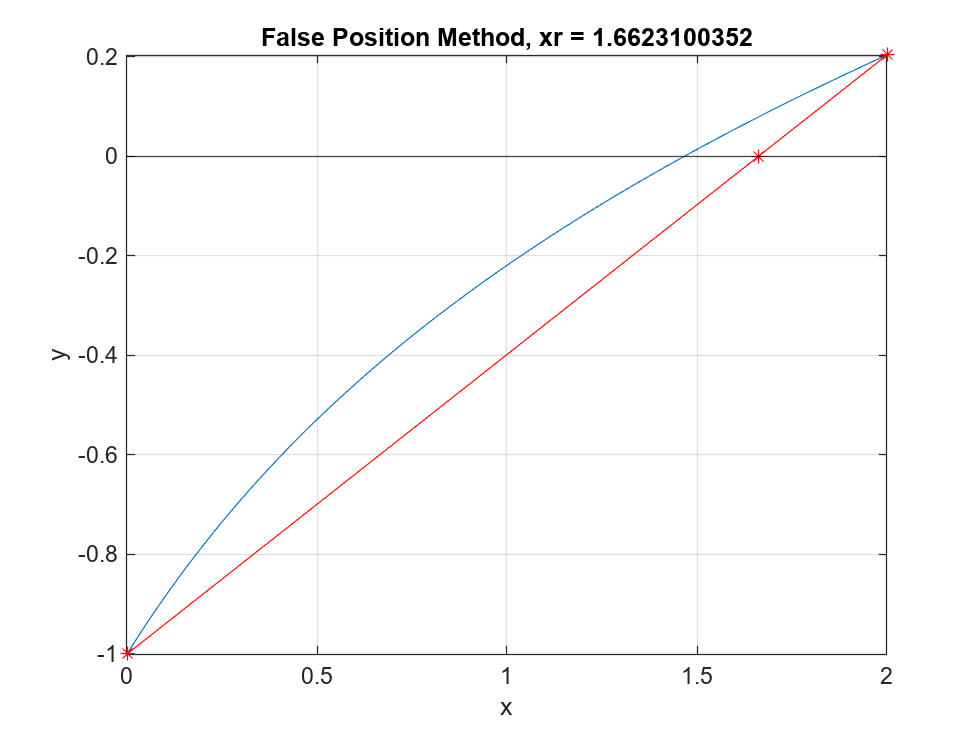

xlower = 0.000000000000000


xupper = 2.000000000000000


xroot = 1.662310035239804


f(xlower) = -1.000000000000000


f(xupper) = 0.203144995579288


f(xroot) = 0.078923040438440


Approximate error = 100.000000000000000

True error = 13.283420421307696

Iteration of 1


xlower = 0.000000000000000


xupper = 1.662310035239804


xroot = 1.540712333443443


f(xlower) = -1.000000000000000


f(xupper) = 0.078923040438440


f(xroot) = 0.030399511689291


Approximate error = 7.892304043844041

True error = 4.996757113716726

Iteration of 2


xlower = 0.000000000000000


xupper = 1.540712333443443


xroot = 1.495257243394378


f(xlower) = -1.000000000000000


f(xupper) = 0.030399511689291


f(xroot) = 0.011660319194052


Approximate error = 3.039951168929130

True error = 1.899074992358552

Iteration of 3


xlower = 0.000000000000000


xupper = 1.495257243394378


xroot = 1.478023023168082


f(xlower) = -1.000000000000000


f(xupper) = 0.011660319194052


f(xroot) = 0.004464755099679


Approximate error = 1.166031919405160

True error = 0.724594074755623

Iteration of 4


xlower = 0.000000000000000


xupper = 1.478023023168082


xroot = 1.471453344344978


f(xlower) = -1.000000000000000


f(xupper) = 0.004464755099679


f(xroot) = 0.001708387228292


Approximate error = 0.446475509967857

True error = 0.276882352890687

Iteration of 5


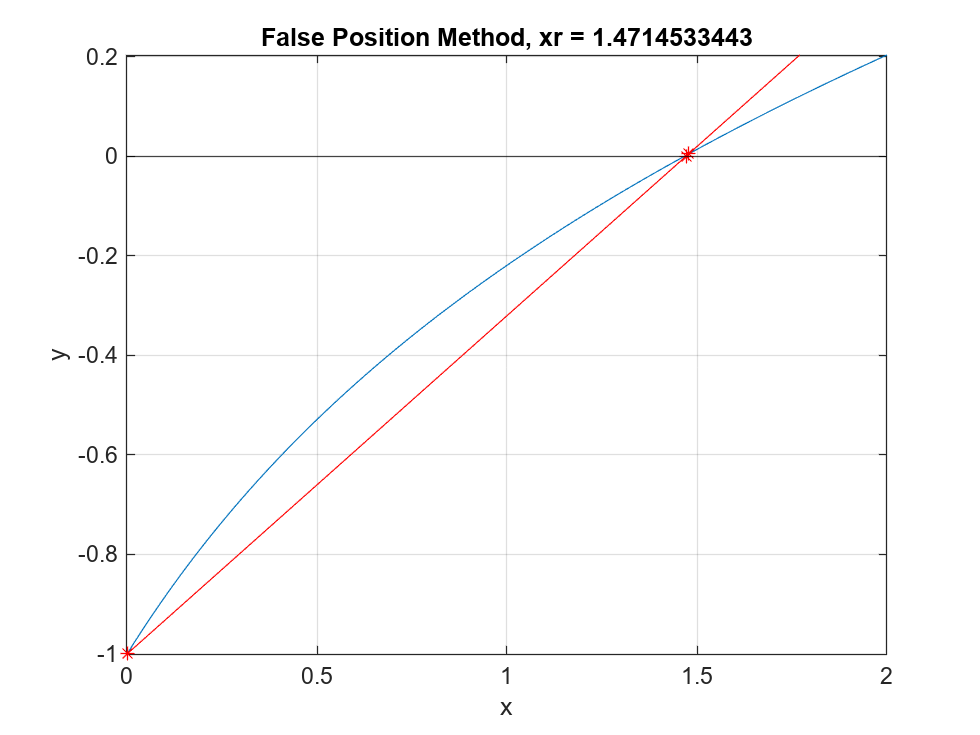

clc, clf

% Bisection Method

% Initializing first two points
xlower = 0; 
xupper = 2;

% Initialize number of iteration
iter = 0;

% Declare stopping error
es = 1;

% Declare boolean
stop_iter = false;

% Loop until approximate error less than stopping error
while (~stop_iter)
    % Get the previous root (except when first iteration
    if (iter >= 1)
        xroot_prev = xroot;
    end

    % Get the root of line connecting xlower and xupper (the false root)
    xroot = xlower - f(xlower) * (xupper - xlower) / (f(xupper) - f(xlower));

    % Increment the number of iteration
    iter = iter + 1;

    % Get the new approximate error
    if (iter > 1)
        ea = abs(xroot - xroot_prev) / xroot * 100;
    else
        ea = 100;
    end
    
    % Get the new true erro
    et = abs(xroot - xr) / xr * 100;

    % Print the current information
    fprintf("xlower = %.15f\n", xlower);
    fprintf("xupper = %.15f\n", xupper);
    fprintf("xroot = %.15f\n", xroot);

    fprintf("f(xlower) = %.15f\n", f(xlower));
    fprintf("f(xupper) = %.15f\n", f(xupper));
    fprintf("f(xroot) = %.15f\n", f(xroot));

    fprintf("Approximate error = %.15f", ea);
    fprintf("True error = %.15f", et);

    fprintf("Iteration of %d\n", iter);

    xs = linspace(0,2,100);
    fs = f(xs);
    os = zeros(100);

    xes = [xlower, xupper];
    yes = f(xes);

    plot(xs,fs);

    hold on
    yline(0, 'black');
    hold off

    hold on
    plot(xes,yes,"r*");
    hold off

    hold on
    plot(xroot,0,"r*")
    hold off

    hold on
    plot(xs, linef(xs, xlower, xupper), 'red');
    hold off

    hold on
    grid on
    hold off

    xlabel("x");
    ylabel("y")

    xlim([0 2]);
    ylim([f(0) f(2)]);

    to_title = sprintf("False Position Method, xr = %.10f", xroot);
    title(to_title);

    pause(2)

    % Check current error
    if (ea < es)
        % Toggle stop iteration
        stop_iter = true;
    else
        % If the sign of f(xroot) is different than f(xlower), then xroot become the
        % new xupper. Otherwise, otherwise.
        if (f(xroot) * f(xlower) < 0)
            xupper = xroot;
        else
            xlower = xroot;
        end
    end
end

Functions

function f = f(x)

g = 9.8;
v = 5;
L = 4;
t = 2.5;

f = (sqrt(2 .* g .* x) ./ v) .* tanh(sqrt(2 .* g .* x) .* t ./ (2 .* L)) - 1;

end

% For false position method
function y = linef(x, xlower, xupper)

y = f(xlower) + (x - xlower) * (f(xupper) - f(xlower)) / (xupper - xlower);

end